ImageRegistrationUsingPhaseCorrelation

Ref to：openExample('images/UsePhaseCorrelationAsPreprocessingStepInRegistrationExample')

[https://ww2.mathworks.cn/help/images/use-phase-correlation-as-preprocessing-step-in-registration.html](https://ww2.mathworks.cn/help/images/use-phase-correlation-as-preprocessing-step-in-registration.html)

Estimate the registration required to bring these two images into alignment. `imregcorr` returns an `affine2d` object that defines the transformation.


% uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\align test1_1\field0001\CyOFP\imageCyOFP00001.tif',1)
% uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\align test1_1\field0001\CyOFP\imageCyOFP00002.tif',1)
% fixed = CyOFP_10001;
% moving = CyOFP_10002;
fixed = imageCyOFP00001;
moving = imageCyOFP00002;
% fixed = im2double(fixed);
% moving = im2double(moving);
% tformEstimate = imregcorr(moving,fixed,'translation');
%Type of transformation xy shift considered as translation

tformEstimate = imregcorr(moving,fixed);

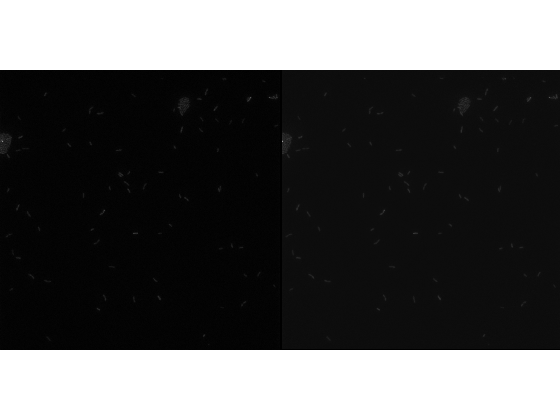

Rfixed = imref2d(size(fixed));
movingReg = imwarp(moving,tformEstimate,'OutputView',Rfixed);
imshowpair(fixed,movingReg,'montage');

View the aligned image overlaid on the original image, using `imshowpair`. In this view, `imshowpair` uses color to highlight areas of misalignment.

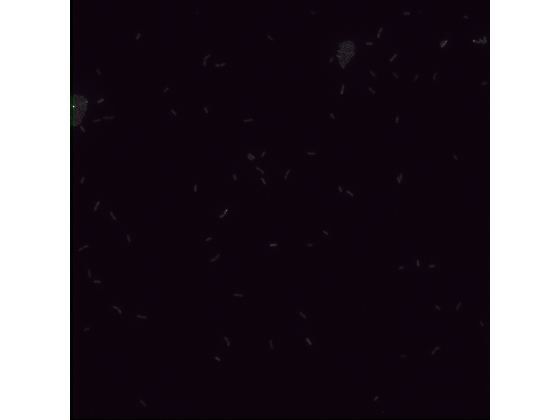

imshowpair(fixed,movingReg,'falsecolor');

To finish the registration, use `imregister`, passing the estimated transformation returned by `imregcorr` as the initial condition. `imregister` is more effective if the two images are roughly in alignment at the start of the operation. The transformation estimated by `imregcorr` provides this information for `imregister`. 

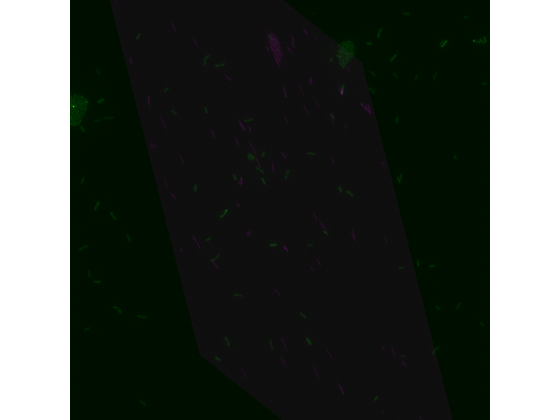

% [optimizer, metric] = imregconfig('monomodal');
% movingRegistered = imregister(moving, fixed,...
%     'affine', optimizer, metric,'InitialTransformation',tformEstimate);
% imshowpair(fixed, movingRegistered,'Scaling','joint');

% uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10001.tif',1)
% uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10002.tif',1)

fixed = CyOFP_10001;
moving = CyOFP_10002;

% fixed = im2double(fixed);
% moving = im2double(moving);
% tformEstimate = imregcorr(moving,fixed,'translation');
%Type of transformation xy shift considered as translation
%结果来看，只是平移的话，效果不好，必须加了旋转才行
tformEstimate = imregcorr(moving,fixed);

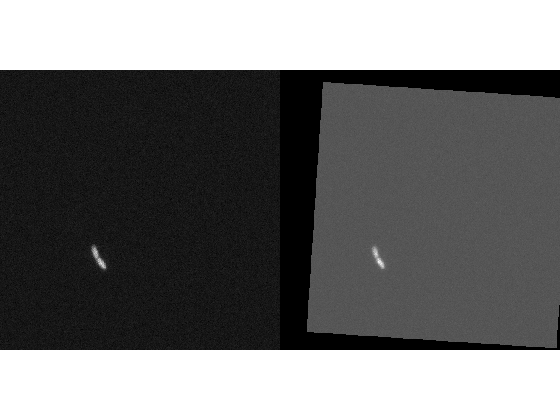

Rfixed = imref2d(size(fixed));
movingReg = imwarp(moving,tformEstimate,'OutputView',Rfixed);
imshowpair(fixed,movingReg,'montage');

View the aligned image overlaid on the original image, using `imshowpair`. In this view, `imshowpair` uses color to highlight areas of misalignment.

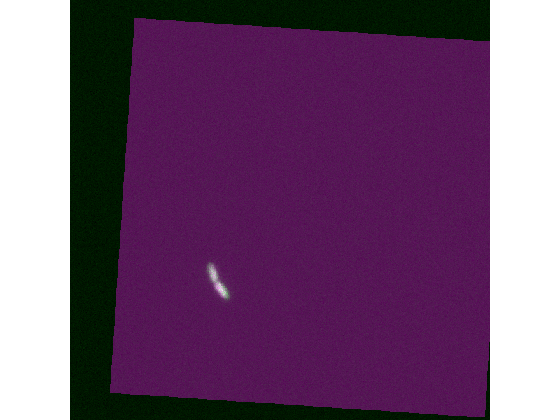

imshowpair(fixed,movingReg,'falsecolor');